Black Box - Clare McMahon, Anthony Marcolini

clear
clc
excel_table=readtable('Black Box.xlsx');
excel=table2array(excel_table);
frequency_hz=excel(:,1); %Hz
a=excel(:,2); %mv
b=excel(:,3); %mv
deltat_ms=excel(:,4); %ms

Time Conversion

deltat=deltat_ms.*10^-3; %seconds

Magnitude Calculations

m_db=20*log10(b./a); %db

Phase Calculation

w=frequency_hz*2*pi;
phase=-2*pi*frequency_hz.*deltat;
phase=rad2deg(phase);

Plot

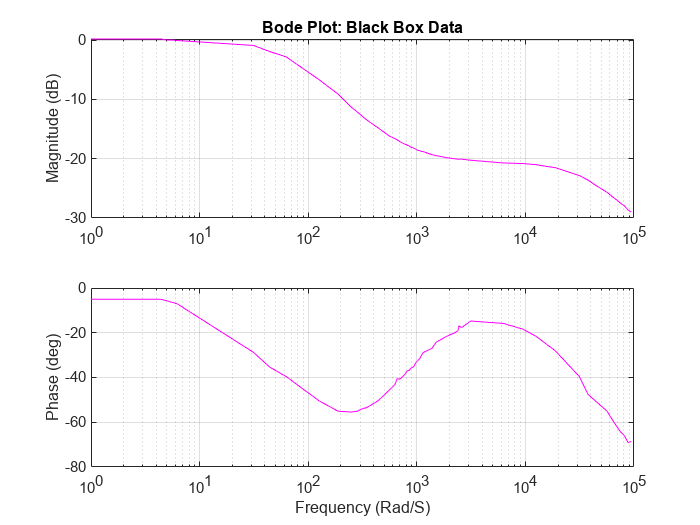

figure (1)
subplot(2,1,1)
semilogx(w,m_db,'m')
xlim([1 10^5])
grid on
title("Bode Plot: Black Box Data")
ylabel("Magnitude (dB)")
subplot(2,1,2)
semilogx(w,phase, 'm')
xlim([1 10^5])
grid on
ylabel("Phase (deg)")
xlabel("Frequency (Rad/S)")

Transfer Function Hand Calculations

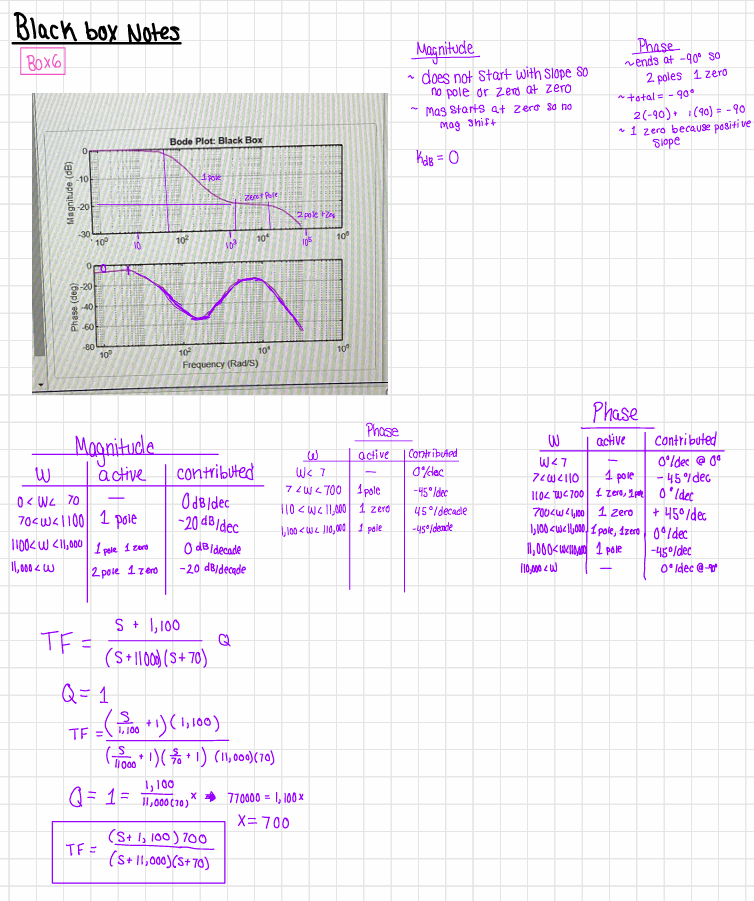

Transfer Function to Bode

Overall layout of equation from above but tweak values to fit better

p1=55; %first pole
p2=26000; %second pole
zero=500; %zero value
q=(p1*p2)/zero; %find gain
a=1; %first poly value
b=p1+p2; %second poly value
c=p1*p2; %third poly value
z=q*zero; %zero poly value


tf_denom=[a b c];
tf_num=[q z];
tf=tf(tf_num,tf_denom);
[mag_tf,phase_tf,w_tf]=bode(tf);
mag_tf = reshape(mag_tf,[],size(mag_tf,2),1);
phase_tf = reshape(phase_tf,[],size(phase_tf,2),1);
mag_tf=20*log10(mag_tf); %to decibels

Transfer Function Plot

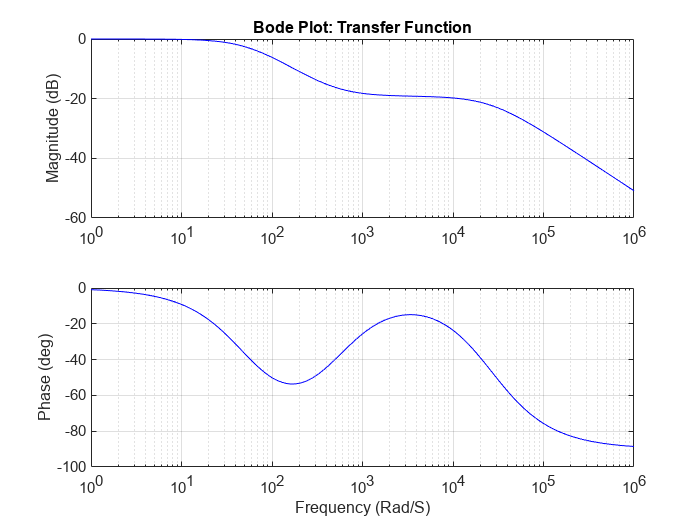

figure (10)
subplot(2,1,1)
semilogx(w_tf,mag_tf,'b')
grid on
title("Bode Plot: Transfer Function")
ylabel("Magnitude (dB)")
subplot(2,1,2)
semilogx(w_tf,phase_tf, 'b')
grid on
ylabel("Phase (deg)")
xlabel("Frequency (Rad/S)")

Overlay Data and transfer function

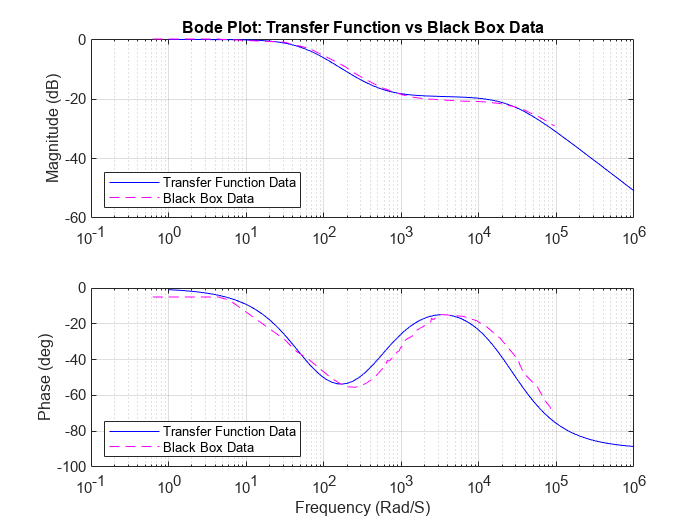

figure (17)
subplot(2,1,1)
semilogx(w_tf,mag_tf,'b')
hold on 
semilogx(w,m_db,'--m')
grid on
title("Bode Plot: Transfer Function vs Black Box Data")
ylabel("Magnitude (dB)")
legend('Transfer Function Data','Black Box Data')
legend('location','southwest')
subplot(2,1,2)
semilogx(w_tf,phase_tf, 'b')
hold on
semilogx(w,phase, '--m')
legend('Transfer Function Data','Black Box Data')
legend('location','southwest')
grid on
ylabel("Phase (deg)")
xlabel("Frequency (Rad/S)")

Time Response Check

time_data=load("BlackBox1.txt");
output_v=time_data(:,2);
time=time_data(:,1);
t=NaN(1000,1);
v=NaN(1000,1);
n=1;
dt=0.001;
t(1)=0;
c=600;
while n<200
t(n+1)=t(n)+dt;
v(n)=output_v(c);
n=n+1;
c=c+1;
end
v(n+1)=output_v(c+1);

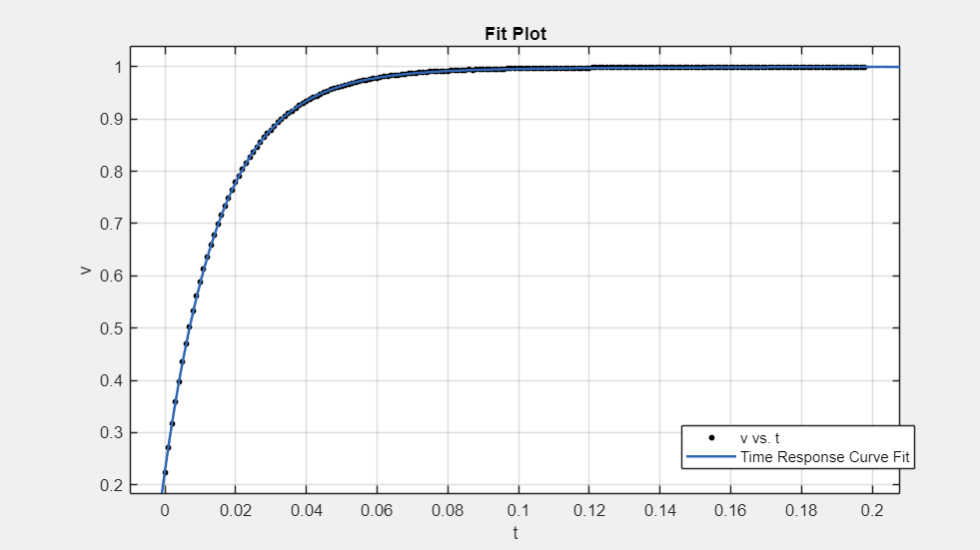

Curve fit from time frequency response data

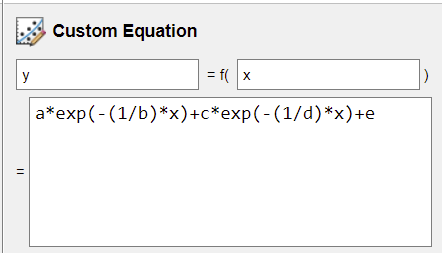

custom equation used to curve fit

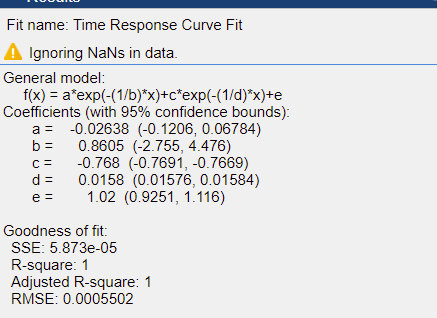

constants from data

a_c=-0.02638;
b_c=0.8605;
c_c=-0.768;
d_c=0.0158;
e_c=1.02;
h=1;
curve=NaN(1,1000);
while h<n
    curve(h)=a_c*exp(-(1/b_c)*t(h))+c_c*exp(-(1/d_c)*t(h));
    h=h+1;
end
curve(h)=a_c*exp(-(1/b_c)*t(h))+c_c*exp(-(1/d_c)*t(h));


Simulink

This script takes the transfer function and inputs a step response into it and output a frequency response

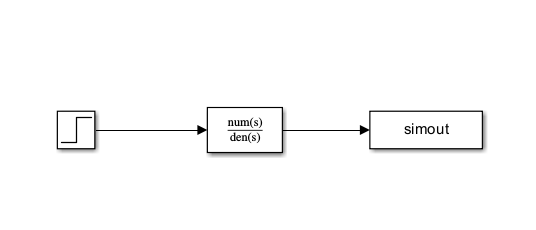

sim("blackbox.slx")

Plot simulink time response against data

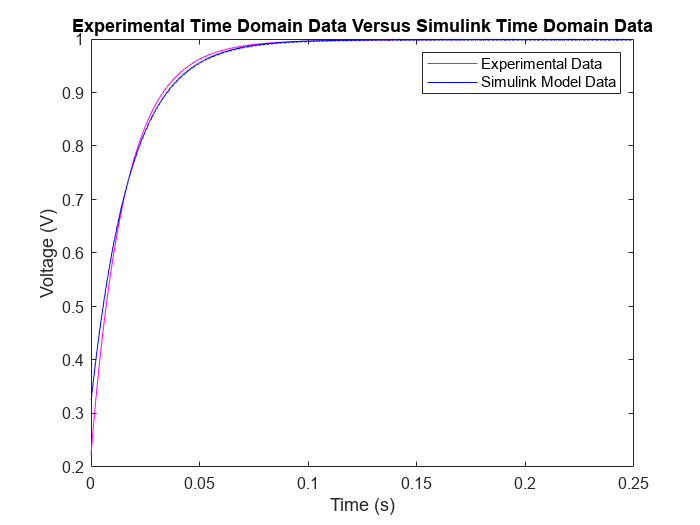

tout=tout(50:2000)-1.005;
simout=simout(50:2000);
figure (20)
plot(t,v, 'm')
hold on
plot(tout,simout, 'b')
legend on
legend("Experimental Data", 'Simulink Model Data')
xlabel('Time (s)')
ylabel('Voltage (V)')
title("Experimental Time Domain Data Versus Simulink Time Domain Data")